% parameters
N = 100 ;
standard_err_value = 1e-4;
[p,x_start,t_start,t_stop,max_dt_FE] = getParam_HeatBar(N, 1000);
x0 = sparse(zeros(N,1)); %%% ALso have to play 
timestep = 1e-5;
eval_f = 'eval_f_LinearSystem';
eval_u = 'eval_u_step';
visualize = 0;


% Reference Solution and err_ref DO NOT RUN
[X_ref, t_ref] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,1,visualize);
err_ref = [];
for i=3:5
    timestep = 10^(-i);
    [X,t] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
    err_ref(end + 1) = norm(X(:, end) - X_ref(:, end), Inf);
    X_ref = X;
    t_ref = t;
end
err_ref


save 'reference.mat' X_ref err_ref

t_new_end = 1.5
timestep = 1e-5;
[X_cont,t_cont] = ForwardEuler(eval_f,X_ref(:, end),p,eval_u,t_stop,t_new_end,timestep,visualize);


% Err_unstable
load reference.mat;
err_unstable = [];
for i=-4:3
    timestep = 10^(-i);
    [X,t] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
    err_unstable(end + 1) = norm(X(:, end) - X_ref(:, end), Inf);
end
err_unstable

% Dynamic delta_t
timestep = 10^(-4);
tic;
[X_fe,t_fe] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
toc
err_fe = norm(X_fe(:, end) - X_ref(:, end), Inf)
plot()

timestep = .25;
tic;
[X_tr,t_tr] = Trapezoidal_Dynamic(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);

    0.2500

    0.5000

    0.7500



toc

Elapsed time is 8.593179 seconds.


err_trp = norm(X_tr(:, end) - X_ref(:, end), Inf)

err_trp = 0.0786

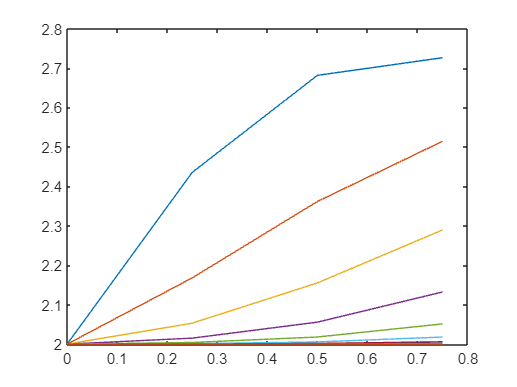

for i=1:100
plot(t_tr, X_tr(i, :))
hold on
end
hold off

timestep = 10^(-2);
tic;
[X_trap,t_trap] = Trapezoidal(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
toc
err_trap = norm(X_trap(:, end) - X_ref(:, end), Inf)

err_fe = norm(X_fe(:, end) - X_ref(:, end), Inf)
err_trp = norm(X_tr(:, end) - X_ref(:, end), Inf)
